# **IO3xx Resolver Measurement**

This example demonstrates how to set up the Resolver Measurement code module for the IO3xx-24 I/O interface extension.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed with -24 I/O interface extension

- A Speedgoat configuration file that supports **1 x Resolver Measurement channel**  

- Connector cable from the I/O module to the terminal board

- Terminal board

- Resolver (detached or mounted in an electrical machine)

### Test Setup

In this example, a Resolver Measurement channel of the IO3xx-24 I/O interface extension is used to measure the position and rotational speed of a connected resolver. The resolver must be connected to the Resolver Measurement channel one on the IO3xx-24 terminal board. The exact pins are indicated in the pin mapping of your configuration file (bitstream). You can access the pin mapping with the Pin Mapping button in the IO3xx Setup v3 block. In the pin mapping, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect theses pins to the Resolver.

The module generates a differential excitation sine wave signal as input for the Resolver. Inputs to the module are the differential sine and cosine output signals of the resolver.

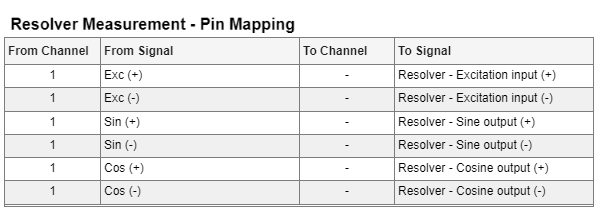

## Initialize and Open the Simulink model

*Add commands to configure parameters and other settings.*

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Resolver_Measurement';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

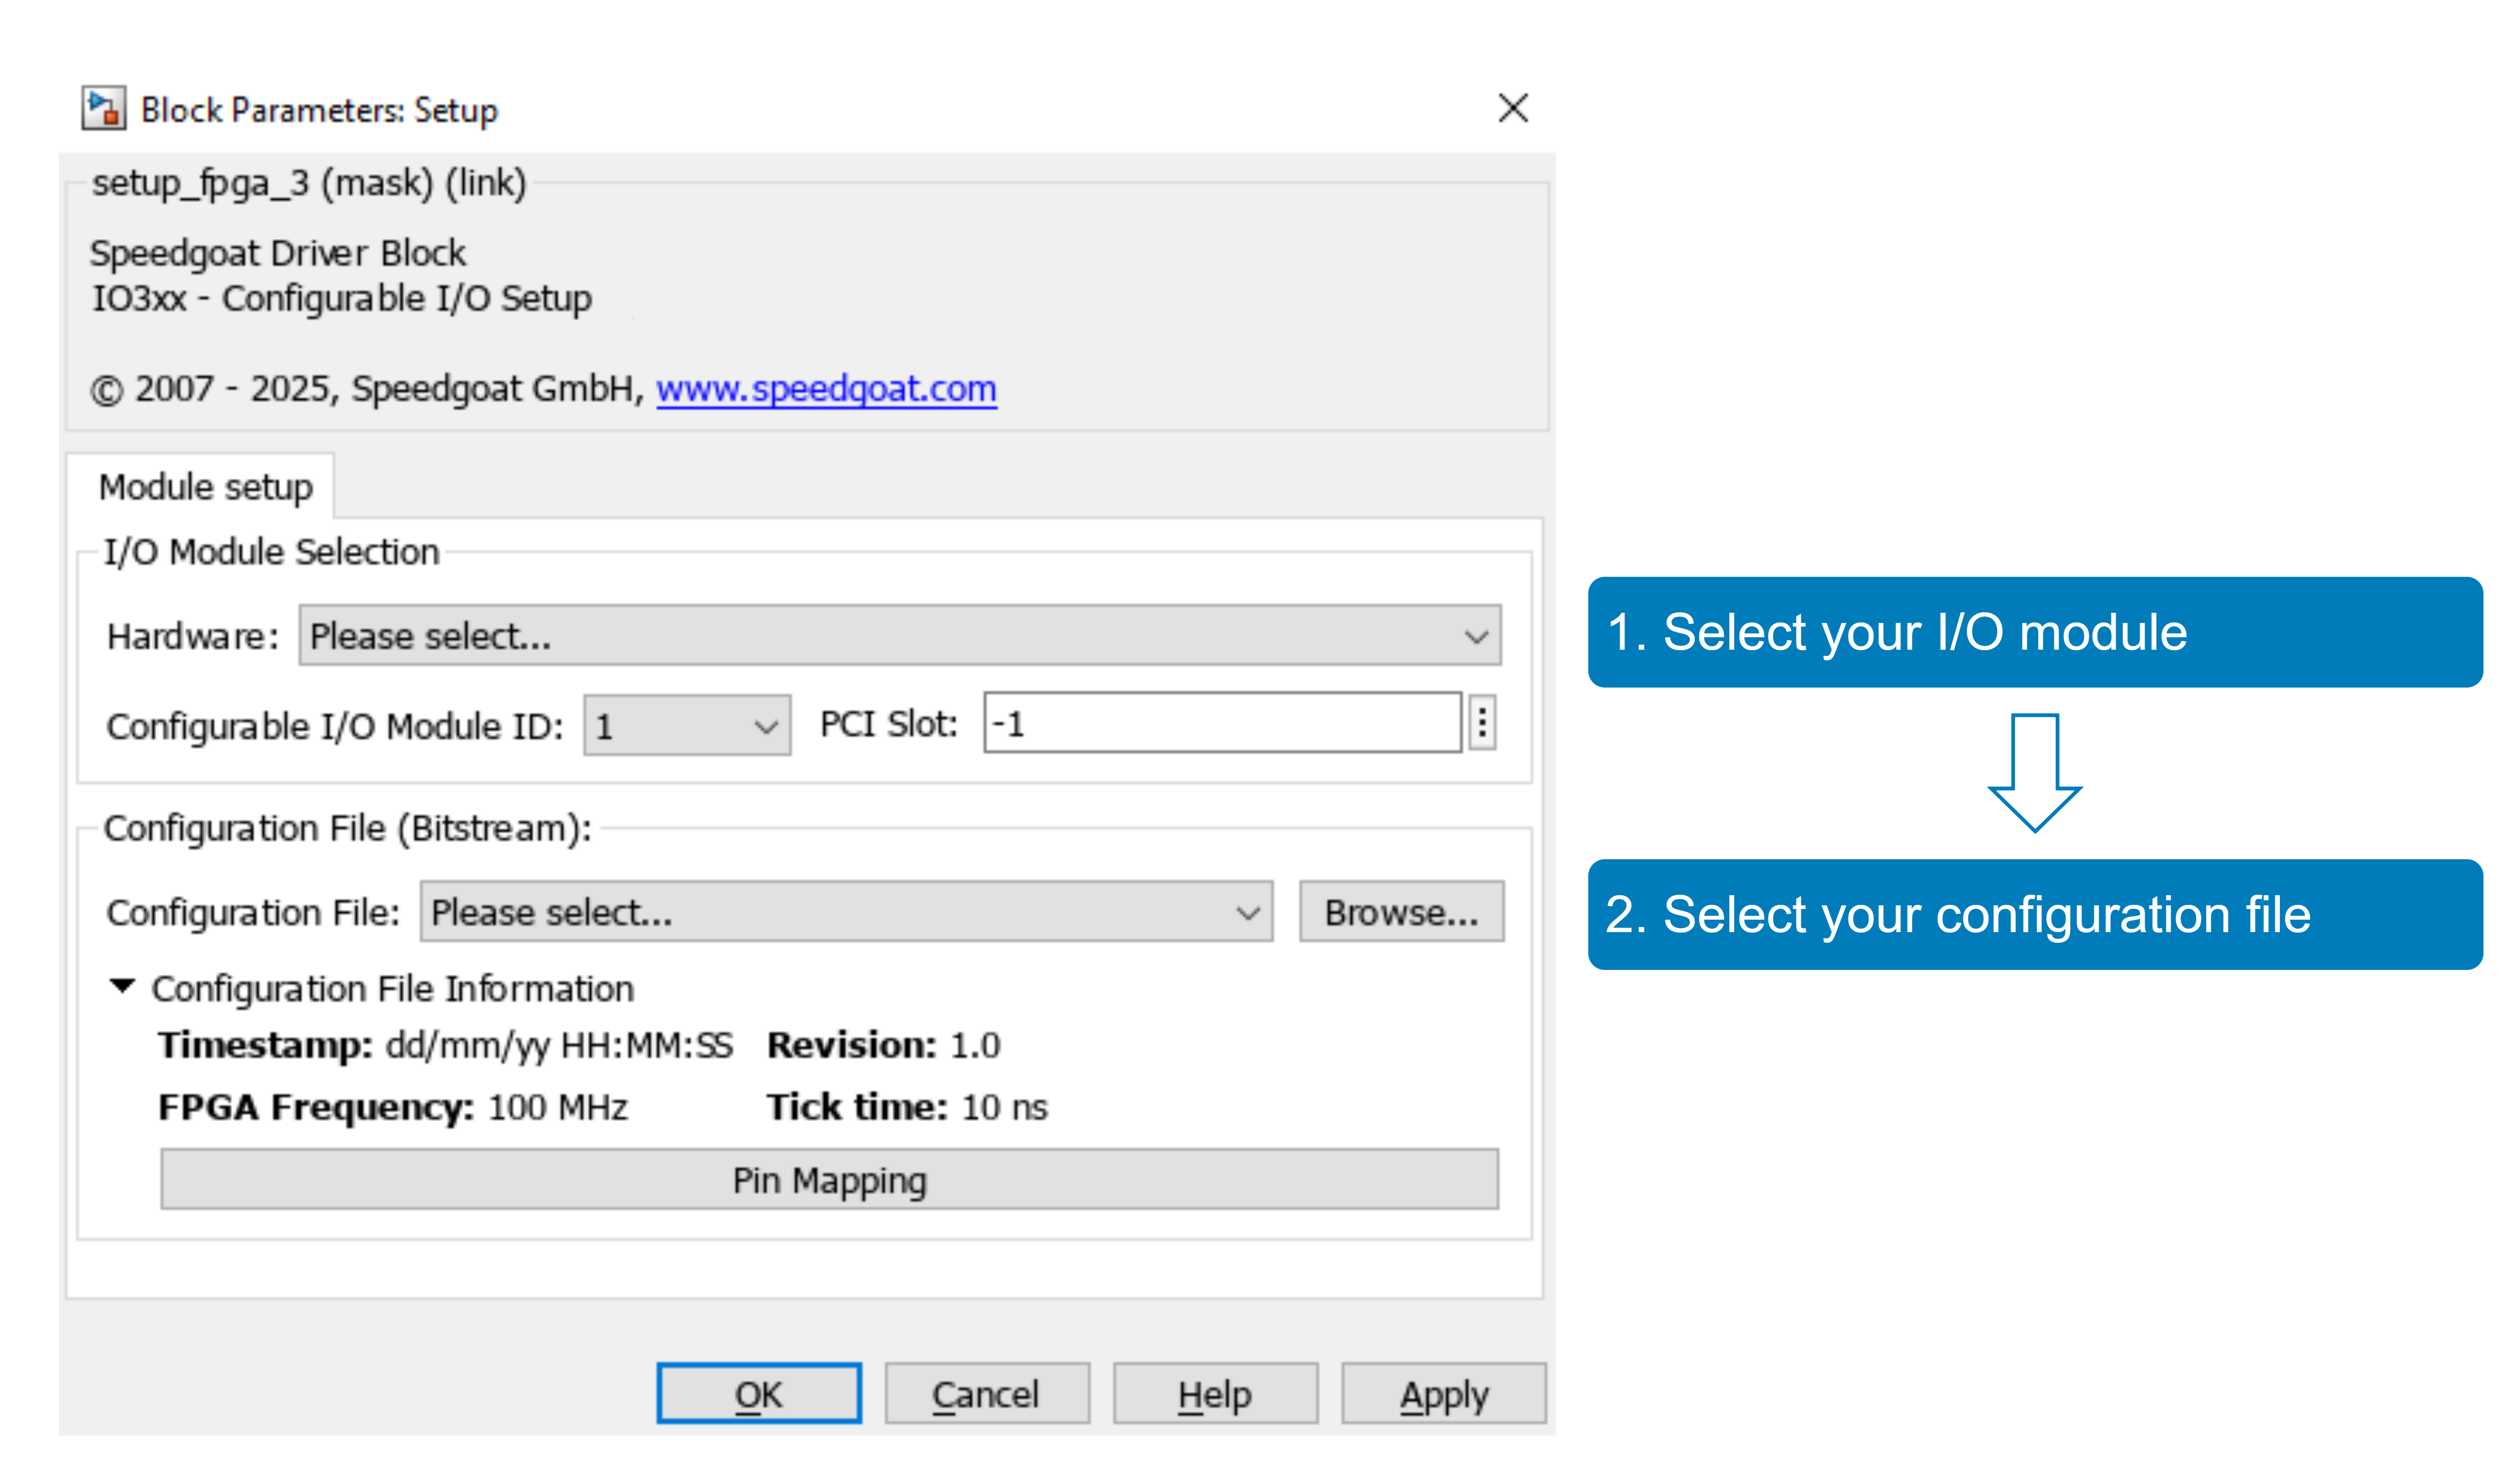

With the **Pin Mapping** button you can now check where the functionalities are located.

### Model Description

The simple example model contains the IO3xx Setup v3 block to initialize the configurable I/O module and one instance of the Resolver Measurement block to configure the Resolver Measurement channel.

**Code Module Setup**

The Resolver Measurement block runs at a sample time step of 100 microsecond. The speed and position values are obtained from a Resolver to Digital Converter (RDC). The block provides three trigger options:

- **Free running**: Position and speed are sampled as fast as possible. The CPU driver block reads the latest available samples.

- **Model step**: Speed and position samples are triggered when the CPU driver block wakes up. The sampled value from the previous sample step is available in the Simulink model. This prevents the driver block from waiting for the completion of the data transfer or the latest sample.

- **I/O module digital I/O**: The speed and position sample can be triggered by the rising or falling edge of any digital I/O signal. Use this option to synchronize the resolver measurement with another code module. When the driver block is executed on the CPU, it reads out the latest available sample. Use an interrupt to synchronize the CPU with the speed and position sampling.

The example model uses the **Model step** trigger setting.

Only the first channel is enabled in the RDC Channel 1 tab. The RDC is configured to operate at a resolution of 16 bits. The frequency of the excitation signal is 10 kHz with a differential output voltage of 3 Vrms. The example assumes a resolver with a transfer ratio of 1. The input signal conditioning for the sine and cosine feedback signals is set up for a voltage of 3 Vrms.

**Speed and Postion Output**

The block outputs the speed in Rounds Per Second (RPS) and position in degrees.

**Clear Fault Input**

The RDC indicates different fault states (for example a degradation of the resoler signals) in a fault register. The fault register can be cleared (reset to zero) with a low to high transition at the **Clear Fault** input. If the fault register does not remain at zero after a clear fault operation, this means that the fault state persists. The content of the 8 bit fault register is accessible at the **Fault** output signal of the block.

All input and output ports of the block can be enabled independently in the **Input and Output Port Configuration** tab of the block mask.

The three output signals of the Resolver Measurement block are selected for logging with the Simulation Data Inspector (SDI). The logging is indicated by the blue symbol.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Run the following section to plot the measured speed, position, and fault register signals in the Simulation Data Inspector.

 
% Clear and set up the SDI view
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(3,1);

% Get the last run
allIDs = Simulink.sdi.getAllRunIDs;
lastRunID = allIDs(end);
lastRun = Simulink.sdi.getRun(lastRunID);

% Get the speed and position signals of both crank channels
Speed = lastRun.getSignalsByName('Resolver Measurement - Speed');
Position = lastRun.getSignalsByName('Resolver Measurement - Position');
FaultRegister = lastRun.getSignalsByName('Resolver Measurement - Fault Register');

% Display the speed and position of both crank channels
plotOnSubPlot(Speed,1,1,true);
plotOnSubPlot(Position,2,1,true);
plotOnSubPlot(FaultRegister,3,1,true);

% Set time and y range for sub plots
Simulink.sdi.setSubplotLimits(1,1,'tRange',[1.8,2.2]);
Simulink.sdi.setSubplotLimits(1,1,'yrange',[0,110]);
Simulink.sdi.setSubplotLimits(2,1,'yrange',[0,360]);
Simulink.sdi.setSubplotLimits(3,1,'yrange',[0,255]);

% View SDI
Simulink.sdi.view;

The following figure shows that the connected resolver is turning at a constant speed of 100 rounds per second. The fault register is zero. No fault is detected.

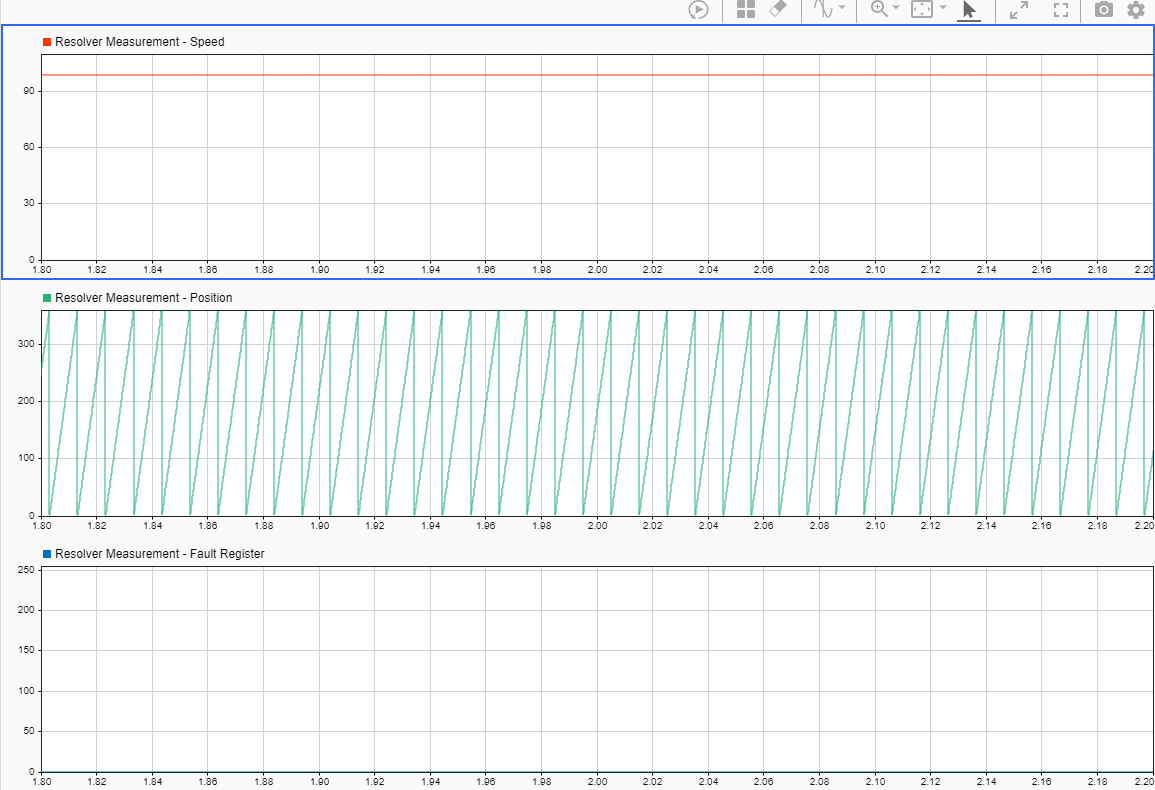

## Additional References

- [Resolver Measurement documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_resolver)